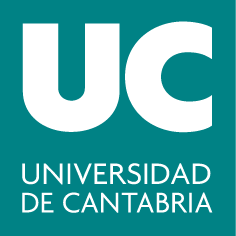

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Cálculo I**

# **10. Derivadas parciales**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Repaso

Hemos estudiado los comandos para calcular las derivadas en el caso de funciones de una variable.

- [`diff`](https://es.mathworks.com/help/symbolic/diff.html)**:** Calcula la derivada de una función de manera simbólica.

Este mismo comando se pueden aplicar a funciones de varias variables.

### Derivadas parciales

Para calcular derivadas parciales de una función de varias variables:

donde:

- `f`: La función simbólica de la cual se desea calcular la derivada.

- `var`: La variable respecto a la cual se tomará la derivada parcial.

**Ejemplo**: Dada la función $$f(x,y)=\frac{e^x}{sen(y)}$$, calcula $$\frac{\partial f}{\partial x}$, $\frac{\partial f}{\partial y}$, $\frac{\partial^2 f}{\partial x^2}$, $\frac{\partial^2 f}{\partial y^2}$ y $\frac{\partial^2 f}{\partial x \partial y}$$ en el punto $$P(-3, \frac{\pi}{2})$$. Comprueba que $$\frac{\partial^2 f}{\partial x \partial y}= \frac{\partial^2 f}{\partial y \partial x}$$.

syms x y real 
f(x,y) = exp(x)/sin(y);  % funcion a derivar

1. Primeras derivadas parciales:

fx(x,y) = diff(f, 1, x)  % primera derivada parcial con respecto a 'x'

$$fx(x, y) = \frac{{\mathrm{e}}^{x}}{\sin\left(y\right)}$$

El el punto $$P(-3, \frac{\pi}{2})$$:

fx_P = fx(-3, pi/2)

$$fx\_P = {\mathrm{e}}^{-3}$$

Con respecto a y:

fy(x,y) = diff(f, y) % con respecto a 'y'

$$fy(x, y) = -\frac{{\mathrm{e}}^{x}\,\cos\left(y\right)}{{\sin\left(y\right)}^{2}}$$

fy_P = fy(-3, pi/2)

$$fy\_P = 0$$

2. Segundas derivadas:

fxx(x,y) = diff(f, 2, x)   % segundas derivadas

$$fxx(x, y) = \frac{{\mathrm{e}}^{x}}{\sin\left(y\right)}$$

fxx_P = fxx(-3, pi/2)

$$fxx\_P = {\mathrm{e}}^{-3}$$

fyy(x,y) = diff(f, 2, y)  

$$fyy(x, y) = \frac{{\mathrm{e}}^{x}}{\sin\left(y\right)}+\frac{2\,{\mathrm{e}}^{x}\,{\cos\left(y\right)}^{2}}{{\sin\left(y\right)}^{3}}$$

fyy_P = subs(fyy, [x, y], [-3, pi/2]) % es lo mismo que fyy(-3, pi/2)

$$fyy\_P(x, y) = {\mathrm{e}}^{-3}$$

Para las derivadas cruzadas tenemos que usar lo siguiente: $$\frac{\partial^2 f}{\partial x \partial y} = \frac{\partial }{ \partial y}\left( \frac{\partial f}{ \partial x}\right)$$

fxy(x,y) = diff(diff(f, x), y)  % derivada cruzada

$$fxy(x, y) = -\frac{{\mathrm{e}}^{x}\,\cos\left(y\right)}{{\sin\left(y\right)}^{2}}$$

fxy_P = fxy(-3, pi/2)

$$fxy\_P = 0$$

O directamente :

fxy(x,y) = diff(f,x,y) % derivamos con respecto a x,  luego con respecto a y.

$$fxy(x, y) = -\frac{{\mathrm{e}}^{x}\,\cos\left(y\right)}{{\sin\left(y\right)}^{2}}$$

fyx(x,y) = diff(f,y,x)

$$fyx(x, y) = -\frac{{\mathrm{e}}^{x}\,\cos\left(y\right)}{{\sin\left(y\right)}^{2}}$$

Para comprobar que $$\frac{\partial^2 f}{\partial x \partial y}= \frac{\partial^2 f}{\partial y \partial x}$$:

simplify(fxy== fyx)  % igualdad derivadas cruzadas

$$ans(x, y) = \mathrm{symtrue}$$

`symtrue` significa que la expresión es cierta.

#### Regla de la cadena

Para una función compuesta $z=f(u,v)$, donde $u$ y $v$ son funciones de $x$ e $y$, la regla de la cadena establece que:

$\frac{\partial z}{\partial x} = \frac{\partial f}{\partial u} \cdot \frac{\partial u}{\partial x} + \frac{\partial f}{\partial v} \cdot \frac{\partial v}{\partial x}$,     $\frac{\partial z}{\partial y} =\frac{\partial f}{\partial u} \cdot \frac{\partial u}{\partial y} + \frac{\partial f}{\partial v} \cdot \frac{\partial v}{\partial y}$�

En MATLAB podemos hacer el cambio de variables más fácilmente:

**1. **Primero, definimos las funciones simbólicas y las variables

**2. **Calculamos las derivadas parciales directamente:

**Ejemplo: **Dada la función$ $w=ze^{(x+y)}$$, siendo $$x=s$, $y=t^2$ y $z=s^2 t$$, calcula $ $\frac{\partial w}{\partial s}$$ y $$\frac{\partial w}{\partial t}$$. 

1. Definimos las funciones simbólicas y las variables:

syms s t x y z real
x = s; y = t^2; z = s^2*t; % primero definimos las funciones x(s,t), y(s,t) y z(s,t)
w = z*exp(x+y)  % funcion a derivar

$$w = s^{2}\,t\,{\mathrm{e}}^{t^{2}+s}$$

MATLAB sustituye las variables $x,y,z$ por correspondientes expresiones en términos de $s, t$.

2. Calculamos las derivadas:

ws = simplify(diff(w, s) )

$$ws = s\,t\,{\mathrm{e}}^{t^{2}+s}\,\left(s+2\right)$$

wt = simplify(diff(w, t) )

$$wt = s^{2}\,{\mathrm{e}}^{t^{2}+s}\,\left(2\,t^{2}+1\right)$$

#### Derivación implícita

Si la ecuación$ $F(x,y,z) =0$$ define a $$z$ $**implícitamente** como función diferenciable de $$x$ e $y$$, entonces

	
$$$$\frac{\partial z}{\partial x} = -\frac{F_x(x,y,z)}{F_z(x,y,z)}, \quad
	\frac{\partial z}{\partial y} = -\frac{F_y(x,y,z)}{F_z(x,y,z)}, \quad F_z(x,y,z) \neq 0.$$$$


**Ejemplo**: Dada la función $$F(x,y,z)=x^2-y^2+2z-4 = 0$$, calcula $$\frac{\partial z}{\partial x}$ y $\frac{\partial z}{\partial y}$$. 

syms x y z real
F = x^2-y^2+2*z-4;  % funcion a derivar
zx = -diff(F, x)/diff(F, z)  % derivacion implicita

$$zx = -x$$

zy = -diff(F, y)/diff(F, z)  % derivacion implicita

$$zy = y$$

### Gradiente

Para calcular el gradiente, se utiliza el comando `gradient`, o se pueden calcular las derivadas utilizando el comando `diff`.

**Ejemplo**: Dada la función $$f(x,y)=\cos^2(x) + sen(2y)$$, calcula $$\vec{\nabla}f$$ en el punto $ $P(1,-1)$$.

Opción 1. comando `diff`:

syms x y real
f(x,y) = cos(x)^2 + sin(2*y); % definimos la función
fx = diff(f, x);   % calculamos las derivadas parciales
fy = diff(f, y); 
gradfP = double([fx(1,-1); fy(1,-1)])  % gradiente en el punto 'P'

gradfP =    -0.9093
   -0.8323


Opción 2: comando` gradient`:

syms x y real
f(x,y) = cos(x)^2 + sin(2*y); % definimos la función
grad = gradient(f)

$$grad(x, y) = \left(\begin{array}{c} -2\,\cos\left(x\right)\,\sin\left(x\right)\\ 2\,\cos\left(2\,y\right) \end{array}\right)$$

gradP = double(grad(1,-1))

gradP =    -0.9093
   -0.8323


Podríamos dibujar la superficie definida por $$f$$ (por ejemplo en el dominio $$x=[-\frac{\pi}{2}, \frac{\pi}{2}] \times y=[-\frac{\pi}{2}, \frac{\pi}{2}]$$), junto con el vector gradiente a $$f$$ en el punto$ $P$$. Para dibujar vectores en MATLAB se usa el comando `quiver`:

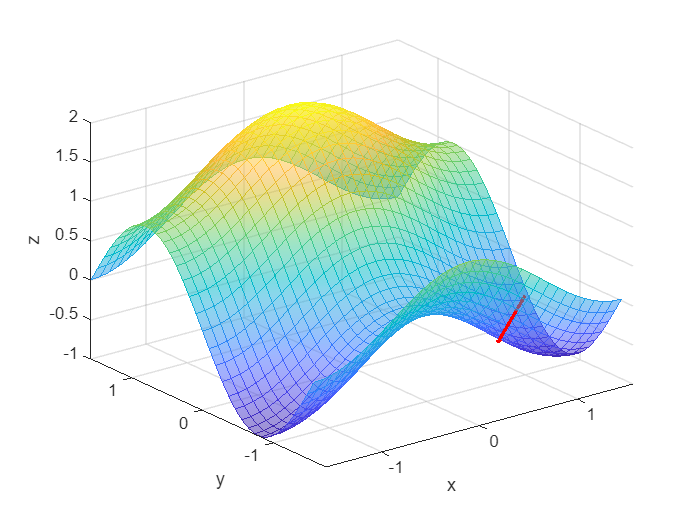

close all
syms x y
f(x,y) = cos(x)^2 + sin(2*y);  % superficie
fsurf(f,[-pi/2 pi/2 -pi/2 pi/2],'EdgeColor','interp','FaceAlpha',0.5)  
xlabel('x'), ylabel('y'), zlabel('z')
hold on
grad = gradient(f);
gradP = double(grad(1,-1));
quiver(1, -1, gradP(1), gradP(2),'r-','LineWidth',2) 

Como sabemos, el vector gradiente se sitúa sobre el plano $$XY$$, por lo que la representación más natural de nuestro problema sería en 2-dimensiones, sobre dicho plano. Para ello, podríamos proyectar algunas curvas de nivel de $$f$$ (por ejemplo, 3) junto con el vector gradiente en $$P$$ :

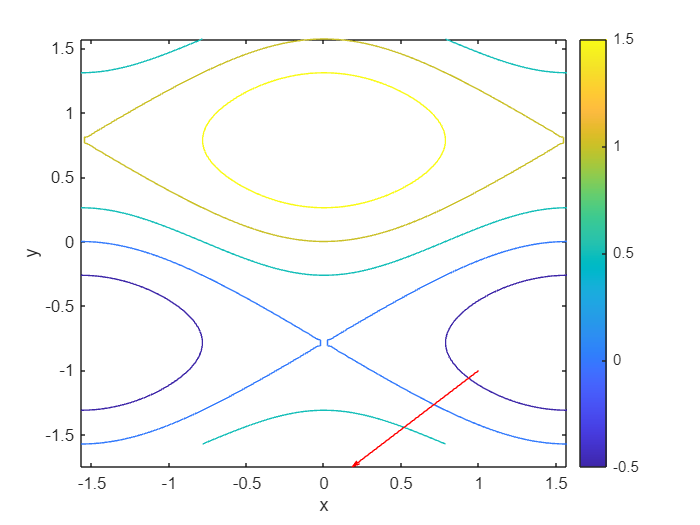

figure
fcontour(f,[-pi/2 pi/2 -pi/2 pi/2])  % curvas de nivel sobre el plano XY
colorbar, xlabel('x'), ylabel('y')
hold on
quiver(1, -1, gradP(1), gradP(2), 'Color', 'r') 

**Ejemplo**: Abre una nueva ventana gráfica. En la mitad izquierda dibuja la superficie  $$f(x,y)=5(x+y)e^{(-x^2 - y^2)}$$, definida sobre el dominio$ $x=[-2,2] \times y=[-3,3]$$. En la izquierda, dibuja las curvas de nivel junto con el campo de vectores $$\vec{\nabla}f$$.

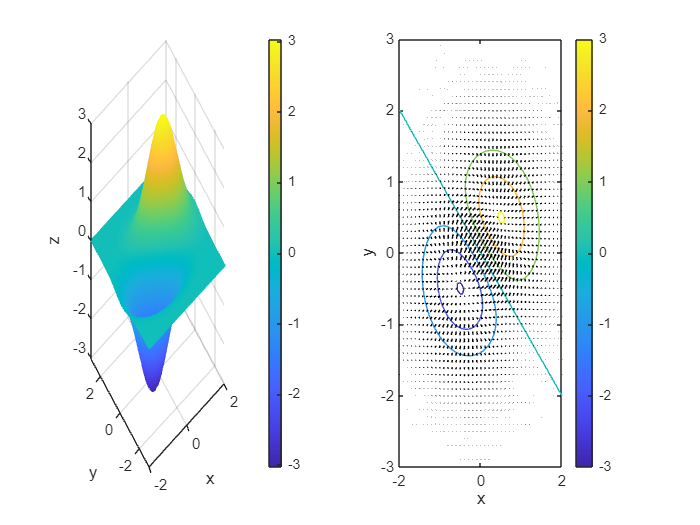

syms x y real 
f(x,y) = 5*(x+y)*exp(-x^2-y^2);
fx = diff(f, x);  
fy = diff(f, y); 
[X, Y] = meshgrid(-2:0.1:2, -3:0.1:3);  % malla que cubre el dominio
G1 = fx(X,Y); % gradiente en los puntos de la malla
G2 = fy(X,Y);
figure  % abro una nueva ventana grafica
subplot(1,2,1)  % subventana izquierda
fsurf(f,[-2 2 -3 3],'EdgeColor','interp')  % superficie
colorbar, xlabel('x'), ylabel('y'), zlabel('z')

subplot(1,2,2)  % subventana derecha
fcontour(f,[-2 2 -3 3])  %curvas de nivel
colorbar, xlabel('x'), ylabel('y')
hold on
quiver(X, Y, G1, G2, 'Color', 'k')

Se puede ver como los vectores gradiente son siempre perpendiculares a las curvas de nivel. Además, el flujo de vectores sale de un mínimo de$ $f$$ (fuente) y llega a un máximo (sumidero). 

Por defecto, el módulo (longitud) de los vectores que dibuja **quiver **no es el real, sino que la propia función hace un reescalado para que no se solapen unos vectores con otros y la representación gráfica mantenga un aspecto `limpio'. Si nos interesase visualizar el módulo real de los vectores, habría que fijar el parámetro opcional `AutoScale` a` off:` 

### Plano tangente

Sea $$S$$ una superficie diferenciable en el punto $$P(x_0, y_0, z_0)$$. La ecuación del plano tangente a $$S$$ en $$P$$ es:

- $ ${F_x(x_0,y_0,z_0)(x-x_0) + F_y(x_0,y_0, z_0) (y-y_0) + F_z(x_0,y_0,z_0) (z-z_0)=0}$$, si $$S$$ viene dada implícitamente como $$S=F(x,y,z)=0$$

- ${z-z_0 = f_x(x_0,y_0)(x-x_0) + f_y(x_0,y_0)(y-y_0)}$, si $$S$$ viene dada explícitamente como$ $S=z=f(x,y)$$

Por tanto, con las funciones `diff y fsurf` podremos calcular y representar el plano tangente a una superficie del tipo $$z=f(x,y)$$ en un punto $$P$$.

**Ejemplo**: Dada la función $$z=f(x,y)=\sqrt{1+\left(\frac{x}{5}\right)^2 + \left(\frac{y}{6}\right)^2}$$.  Representa $$z$ $en el dominio $$x=[-5,5] \times y=[-5,5]$$ y su plano tangente en $$P(0,-1)$$ en $$x=[-3,3] \times y=[-3,3]$$.

Primero, representamos la superficie:

syms x y real
f(x,y) = sqrt(1 + (x/5)^2 + (y/6)^2);  % superficie
figure  % nueva ventana grafica
fsurf(f,'EdgeColor','interp','FaceAlpha',0.5)  % dibujo superficie
xlabel('x'), ylabel('y'), zlabel('z')  

Calculamos las derivadas parciales

fx = diff(f, x);  % parcial de 'f' con respecto a 'x'
fy = diff(f, y);  % parcial de 'f' con respecto a 'y'

Evaluamos la función en el punto P

x0 = 0; y0 = -1;  % punto P
z0 = f(x0, y0);  % valor que toma la superficie en P

Definimos el plano tangente:

PT(x,y) =fx(x0,y0)*(x - x0) + fy(x0,y0)*(y - y0) + z0;  % plano tangente 

Representamos en la misma gráfica

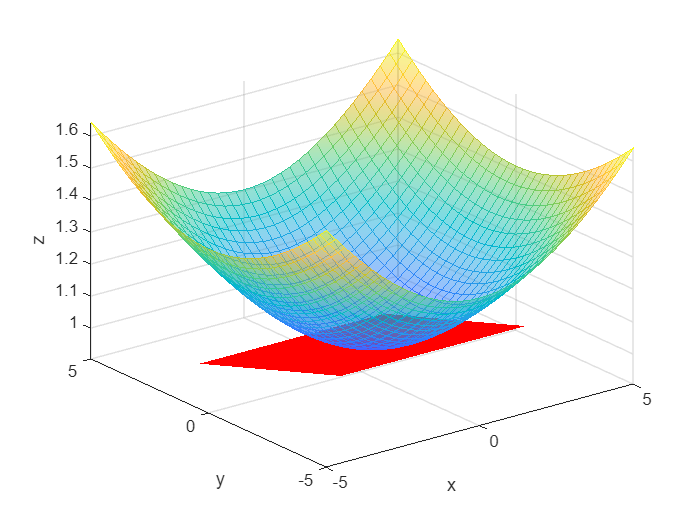

hold on
fsurf(PT,[-3 3 -3 3], 'FaceColor','red','EdgeColor','none')

### **Ejercicios propuestos**

1. Calcula las siguientes derivadas parciales:

- $ $\frac{\partial f}{\partial x}$, $\frac{\partial f}{\partial y}$ y $\frac{\partial f}{\partial z}$ $en el punto$ $P(1,-1,1)$$, siendo $$f=\frac{x}{yz}$$.

- $ $\frac{\partial z}{\partial x}$ y $\frac{\partial z}{\partial y}$$ en el punto $$P(0,1,-2)$$, siendo $$F=e^x sen(y+z)-z=0$$ (Utiliza la derivación implícita).

- 
$$ $\frac{df}{dt}$ en $t=\pi$, siendo $f=xyz$, con $x=t^2$, $y=2t$ y $z=e^{-t}$$$


% escribe aquí el código:
clearvars
close all




Solución:

soluciones(1)


f(x,y,z) = x/(y*z):
f_x(P) = -1.00, f_y(P) = -1.00, f_z(P) = 1.00

F(x,y,z) = exp(x)*sin(y + z) - z:
z_x(P) = -1.83, z_y(P) = 1.18

f(t) = 2*t^3*exp(-t):
df(P) = -0.12


 2. Considera la función  $$f(x,y) = e^x \cos(y) + e^y \cos(x)$$. Abre una nueva ventana gráfica con $$1 \times 2$$ subventanas y:

-  En la mitad izquierda, representa$f(x,y)$ en el dominio $$x=[-1, 7] \times y = [-1, 7]$$. 

- En la mitad derecha, dibuja las curvas de nivel correspondientes a los valores $$k = \lbrace -1000, -500, -250, 0, 250, 500, 1000 \rbrace$$ y el campo de vectores gradiente

% escribe aquí el código:
clearvars
close all





Solución:

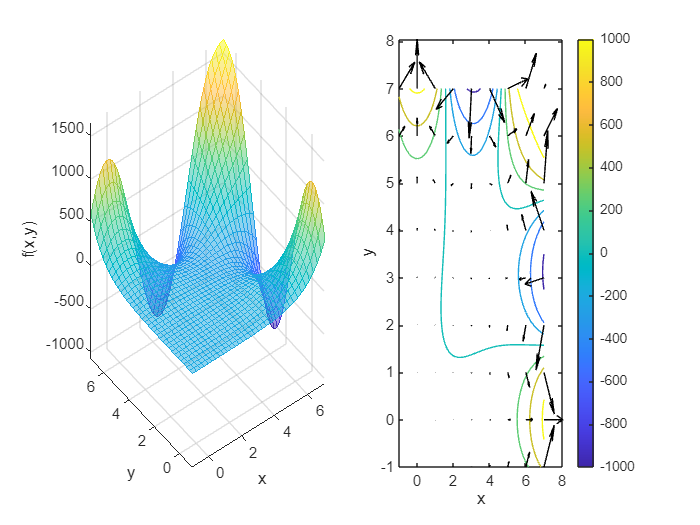

soluciones(2)

3. Considera la función $$f(x,y)=-(x+3)^2 -y^2+3$$. Abre una nueva ventana gráfica con $$1 \times 2$$ subventanas y:

-  En la mitad izquierda, representa $$f$$ en el dominio $$x=[-8,4] \times y = [-8,4]$$, junto con su plano tangente en el punto $$P(-1;0.5)$$, este último sobre el dominio $$x=[-6,2] \times y=[-6,2]$$.

- En la mitad derecha, dibuja las curvas de nivel $$f$$, junto con las curvas de nivel del plano tangente (estas últimas en rojo).

% escribe aquí el código:






Solución:

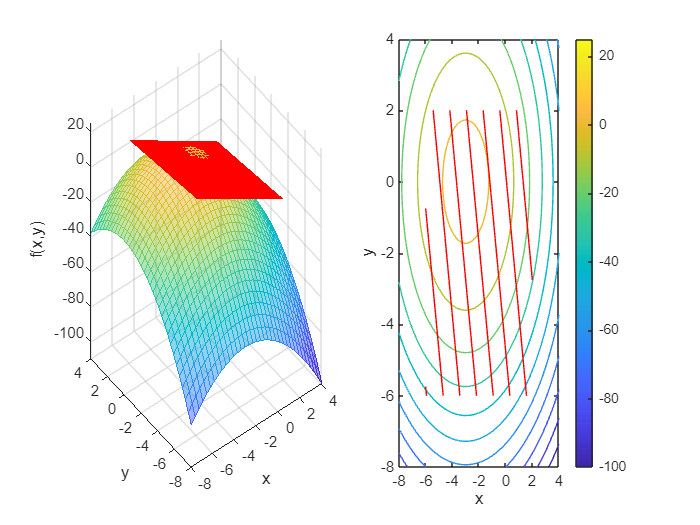

soluciones(3)

4. Considera la función $$f(x,y)=\arctan\left(\frac{x}{y}\right)$$. Calcula el plano tangente a $$f$$ en el punto  $$P(-1.25; 0.5)$.$¿Qué valor toma este plano en el punto $$P_1(1,0)$$?

% escribe aquí el código:



Solución:

soluciones(4)

El plano tangente z=(8*x)/29 + (20*y)/29 - atan(5/2) en el punto P1(1, 0) toma valor -0.9144.


### Resumen

**Derivadas Parciales**

- [`diff(f, var)`](https://es.mathworks.com/help/symbolic/diff.html): Calcula la derivada parcial de la función simbólica `f` respecto a la variable `var`. 

- `diff(f, var1, var2): `para calcular las derivadas cruzadas.

**Derivación Implícita**

- `dzdx = - diff(F, x) / diff(F, z)`: Calcula derivadas implícitas si la función está definida implícitamente como una función de varias variables.

**Gradiente**

- [`gradient(f)`](https://es.mathworks.com/help/symbolic/sym.gradient.html): Calcula el gradiente de una función simbólica `f`, que consiste en las derivadas parciales respecto a todas las variables. 

- [`quiver(X,Y,U,V)`](https://es.mathworks.com/help/matlab/ref/quiver.html)`:` representa flechas con los componentes direccionales `U` y `V` en las coordenadas cartesianas especificadas por `X` e `Y`. Por ejemplo, la primera flecha se origina en el punto `X(1)` e `Y(1)`, se extiende horizontalmente según `U(1)` y se extiende verticalmente según `V(1)`. 

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        syms x y z real
        f(x,y,z) = x/(y*z);
        fx = diff(f,x);
        fy = diff(f,y);
        fz = diff(f,z);
        fx_P = double(fx(1,-1,1));
        fy_P = double(fy(1,-1,1));
        fz_P = double(fz(1,-1,1));
        fprintf("\nf(x,y,z) = %s:\nf_x(P) = %.2f, f_y(P) = %.2f, f_z(P) = %.2f\n", char(f),fx_P, fy_P, fz_P)
        F(x,y,z) = exp(x)*sin(y+z)-z;
        zx = -diff(F,x)/diff(F,z);
        zy = -diff(F,y)/diff(F,z);
        zx_P = double(zx(0,1,-2));
        zy_P = double(zy(0,1,-2));
        fprintf("\nF(x,y,z) = %s:\nz_x(P) = %.2f, z_y(P) = %.2f\n", char(F),zx_P, zy_P)
        syms t real
        x = t^2; y = 2*t; z = exp(-t);
        f = x*y*z;
        ft(t) = diff(f,t);
        ft_P = ft(pi);
        fprintf("\nf(t) = %s:\ndf(P) = %.2f\n", char(f),ft_P)
    case 2
        syms x y real
        f(x,y) = exp(x)*cos(y) + exp(y)*cos(x);
        figure
        subplot(1,2,1)
        fsurf(f,[-1 7 -1 7],'EdgeColor','interp', 'FaceAlpha',0.5)
        xlabel('x'), ylabel('y'),zlabel('f(x,y)');
        subplot(1,2,2)
        fcontour(f,[-1 7 -1 7],'LevelList',[-1000, -500, -250, 0, 250, 500, 1000])
        xlabel('x'), ylabel('y')
        colorbar
        hold on
        fx = diff(f, x);
        fy = diff(f, y);
        [X, Y] = meshgrid(-1:1:7, -1:1:7);  % malla que cubre el dominio
        G1 = fx(X,Y); % gradiente en los puntos de la malla
        G2 = fy(X,Y);
        quiver(X, Y, G1, G2, 'Color', 'k')
        hold off
    case 3
        syms x y real
        f(x,y) = -(x+3)^2-y^2+3;
        fx = diff(f, x);
        fy = diff(f, y);
        x0 = -1; y0 = 0.5;  % punto P
        z0 = f(x0, y0);  % valor que toma la superficie en P
        PT(x,y) =fx(x0,y0)*(x - x0) + fy(x0,y0)*(y - y0) + z0;  % plano tangente
        figure
        subplot(1,2,1)
        fsurf(f,[-8 4 -8 4],'EdgeColor','interp', 'FaceAlpha',0.5)
        xlabel('x'), ylabel('y'),zlabel('f(x,y)');
        hold on
        fsurf(PT,[-6 2 -6 2], 'FaceColor','red','EdgeColor','none')
        hold off
        subplot(1,2,2)
        fcontour(f,[-8 4 -8 4])
        xlabel('x'), ylabel('y')
        colorbar
        hold on
        fcontour(PT,[-6 2 -6 2],'r-')
        hold off
    case 4
        syms x y real
        f(x,y) = atan(x/y);
        fx = diff(f, x);
        fy = diff(f, y);
        x0 = -1.25; y0 = 0.5;  % punto P
        z0 = f(x0, y0);  % valor que toma la superficie en P
        PT(x,y) =fx(x0,y0)*(x - x0) + fy(x0,y0)*(y - y0) + z0;  % plano tangente
        PT_P1 = PT(1,0);
        fprintf("El plano tangente z=%s en el punto P1(1, 0) toma valor %.4f.\n", char(PT),PT_P1);
end

end